# Ballbot robust stability analysis and validation script from worskapce

## It is intended to draw graphs for controllers that have already been calcualted

load workspace
addpath('./generated')
addpath('./visualisation')
addpath('./optimisation')

## Linear and nonlinear model initial condition response comparison

Finally, simple graph of initial condition response for linear and nonlinear system with nominal parameters to see how well does the lienarized system corespond with the nonlinear

nonlinear system simulation
Nonlinear simulation: 4.00 sec / 4.00 sec
Elapsed time is 19.155157 seconds.
lienar system simulation
Elapsed time is 0.041196 seconds.


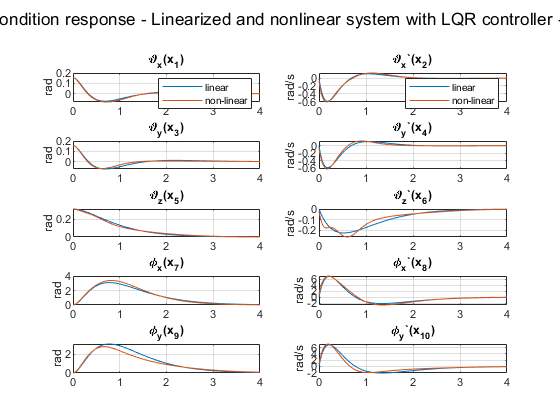

X0 = [pi/20 0 pi/20 0 pi/10 0 0 0 0 0]';
T_max = 4; %s
initialplot_compare_nlin(@nlin_model_n,G_n,K_lqr,X0,T_max,1,2)

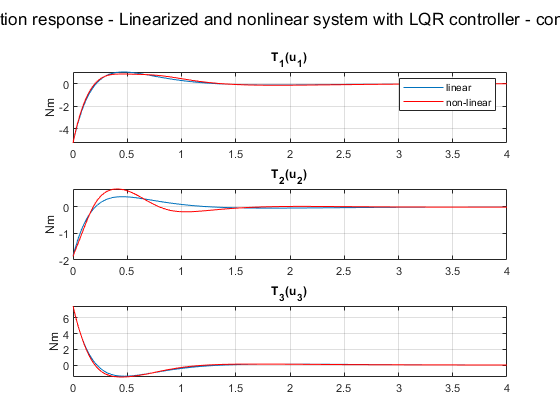

drawnow

## Introducing the uncertainties

The uncertainties are introduced into the physiscal parameters of the system. The idea is that for the variables you cannot measure you should have some uncertainty about their values. 

The uncertainties are set as the percentage. For example if l_var is 20, that means that your height of center of mass can be +-20% different than your nominal value.

% Uncertain variation of the parameters
fprintf('Uncertainty l = %d \n',l_var); % percent

Uncertainty l = 20 


fprintf('Uncertainty A_ThetaAWx = %d \n',A_ThetaAWx_var); % percent

Uncertainty A_ThetaAWx = 10 


fprintf('Uncertainty A_ThetaAWy = %d \n',A_ThetaAWy_var); % percent

Uncertainty A_ThetaAWy = 10 


fprintf('Uncertainty A_ThetaAWz = %d \n',A_ThetaAWz_var); % percent

Uncertainty A_ThetaAWz = 20 


fprintf('Uncertainty ThetaKi = %d \n',ThetaKi_var); % percent

Uncertainty ThetaKi = 20 


fprintf('Uncertainty ThetaWi = %d \n',ThetaWi_var); % percent

Uncertainty ThetaWi = 20 



% sample the uncertain models
kill_figures([100,101]);

Figure 100 not opened
Figure 101 not opened


Sample uncertain models
Uncertain model visualisation - initial condition response
It may take few minutes


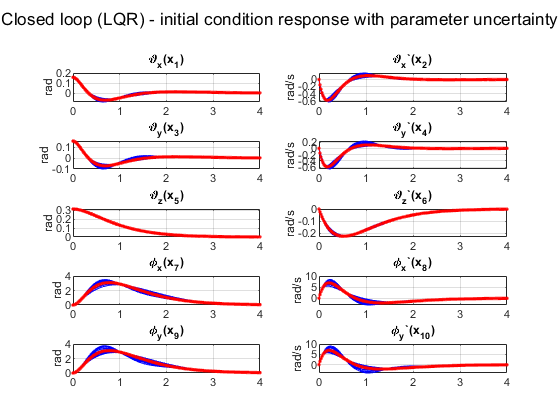

Elapsed time is 18.081642 seconds.
Uncertain model visualisation - singular value plot
It may take few minutes


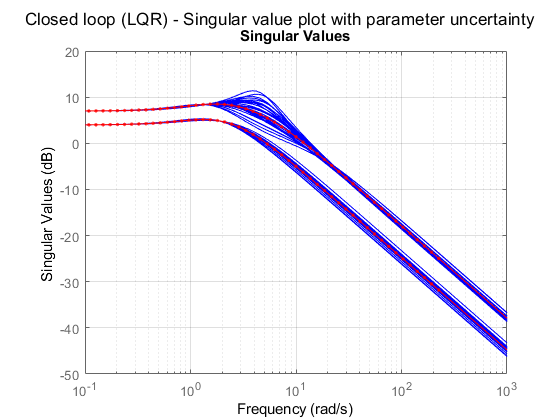

Elapsed time is 15.630070 seconds.


visualise_uncertainty(l_var, ThetaWi_var, ThetaKi_var, A_ThetaAWx_var, A_ThetaAWy_var, A_ThetaAWz_var, K_lqr,100,101);

## The worst case system based on parameter uncertainties

To be able to find the worst case parameters we define the optimisation problem based on disk margin. 

The minimal margin corresponds to the worst case parameters

wcu 

wcu = struct with fields:
             l: 0.1811
       ThetaWi: 0.0180
       ThetaKi: 0.0038
    A_ThetaAWx: 1.5540
    A_ThetaAWy: 1.4835
    A_ThetaAWz: 0.0429
    min_margin: 0.0544
             G: [10×3 ss]
      max_gain: 7.2551


% variable wcu contains 
% wcu.l,ThetaKi,... - the worst case parameters 
% wcu.min_margin    - worst case margin
% wcu.max_gain      - worst case gain
% wcu.G             - linear state space model of the worst case transfer function



## Nominal and worst case linear model comparison

#### Margin comparison

% nominal parameters
MMIO_n = diskmargin(G_n,K_lqr)

MMIO_n = struct with fields:
     GainMargin: [0.8536 1.1715]
    PhaseMargin: [-9.0299 9.0299]
     DiskMargin: 0.1579
     LowerBound: 0.1579
     UpperBound: 0.1582
      Frequency: 3.5389


%worst case parameters
MMIO_wc = diskmargin(wcu.G,K_lqr)

MMIO_wc = struct with fields:
     GainMargin: [0.9471 1.0559]
    PhaseMargin: [-3.1145 3.1145]
     DiskMargin: 0.0544
     LowerBound: 0.0544
     UpperBound: 0.0545
      Frequency: 4.3736


#### Initial condition response

 % initialplot
X0 = [pi/20 0 pi/20 0 pi/10 0 0 0 0 0]';
T_sim = 3; %sec=
kill_figures([110])

Figure 110 not opened


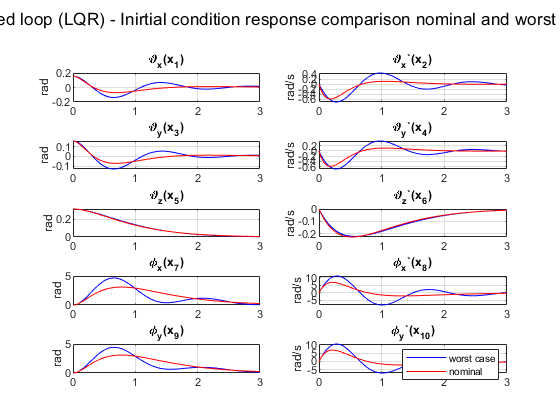

initialplt(feedback(wcu.G,K_lqr),'b',X0,T_sim,110); 
initialplt(feedback(G_n,K_lqr),'r',X0,T_sim,110);
legend('worst case','nominal')
sgtitle('Closed loop (LQR) - Inirtial condition response comparison nominal and worst case')

#### Singular value plota

kill_figures([111]);

Figure 111 not opened


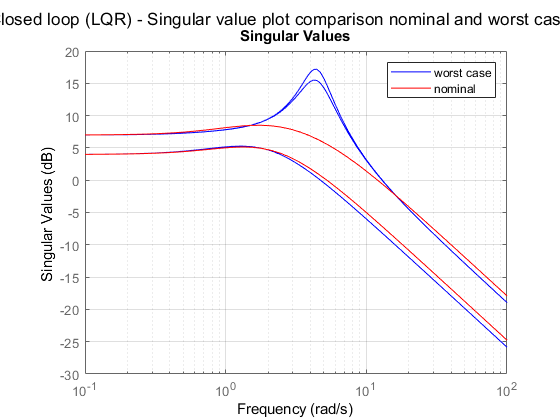

figure(111);
sigma(feedback(wcu.G,K_lqr),'b');
hold on;
sigma(feedback(G_n,K_lqr),'r');
legend('worst case','nominal')
grid on;
sgtitle('Closed loop (LQR) - Singular value plot comparison nominal and worst case')

## Validate worst case performance with the nonlinear model

Interesting is to see if nonlinear system is still stable for worst case parameters and LQR controller calculated for the nominal parameters.

kill_figures([120,121]);

Figure 120 not opened
Figure 121 not opened


% Simulate and compare worst case linear and nonliner
initialplot_compare_nlin(@nlin_model_wcu,wcu.G,K_lqr,X0,T_sim,120,121)

nonlinear system simulation
Nonlinear simulation: 3.00 sec / 3.00 sec
Elapsed time is 20.193124 seconds.
lienar system simulation
Elapsed time is 0.006843 seconds.


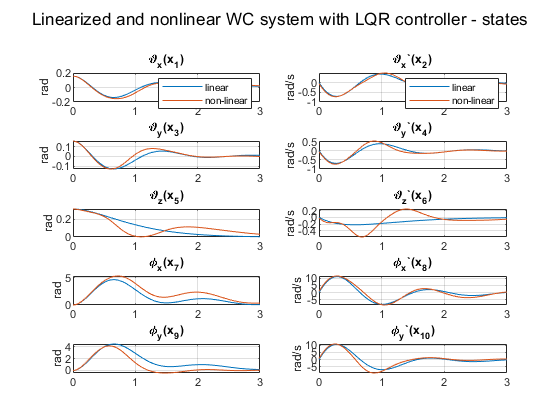

figure(120);
sgtitle('Linearized and nonlinear WC system with LQR controller - states')

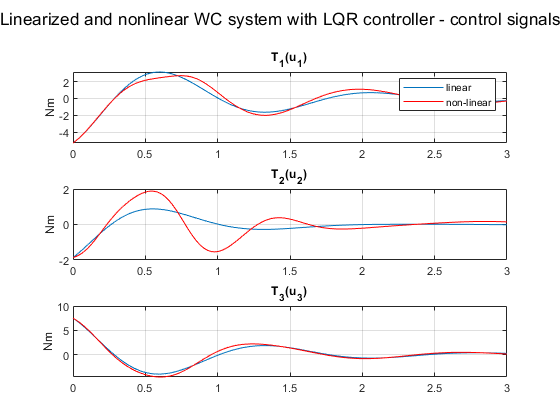

figure(121);
sgtitle('Linearized and nonlinear WC system with LQR controller - control signals')
drawnow

# Distrubance rejection and noise attenuation

#### **Ballbot has two type of disturbance **

 - ***force acting on the body - hunam interaction ****(w)*

 - ***measurement noise *** (*n*)

   > acceletometer and gyro

   > influences thetax, d_thetax, thetay, d_thetay  

#### ** Ballbot system**

 dx = Ax + [B_n B_w B_u]*[w n u]'

 y = Cx + [D_n D_w D_u]*[w n u]'

 u = K*x

% definining the standardized testing input for distrubance rejection
t_d = linspace(0,20,2000);
N_d = length(t_d);
n = randn(4,N_d);
n = n/max(n(:));
wx = [zeros(1,0.2*N_d), ones(1,0.1*N_d), zeros(1,0.7*N_d)];
wy = [zeros(1,0.7*N_d), -ones(1,0.1*N_d) zeros(1,0.2*N_d)];
dist = [n; wx; wy];

kill_figures([200]);

Figure 200 not opened


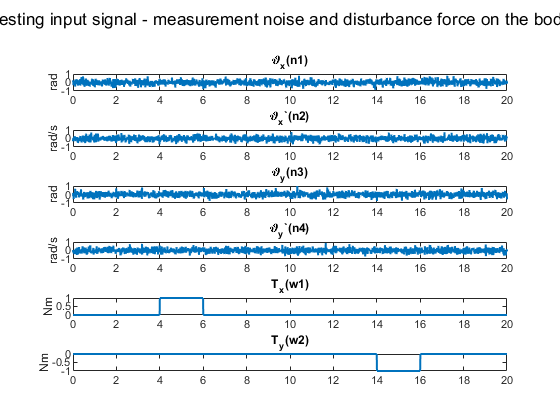

figure(200);
state_var_names = {'\vartheta_x', '\vartheta_x`','\vartheta_y', '\vartheta_y`'};
for i = 1:4
    subplot(6,1,i);
    plot(t_d,dist(i,:),'LineWidth',1.5);
    hold on
    title(strcat(state_var_names{i},'(n',num2str(i),')'))
    if mod(i,2)
        ylabel('rad')
    else
        ylabel('rad/s')
    end
end
w_names={'T_x','T_y'};
for i = 1:2
    subplot(6,1,4+i);
    plot(t_d,dist(4+i,:),'LineWidth',1.5);
    hold on
    title(strcat(w_names{i},'(w',num2str(i),')'))
    ylabel('Nm')
end
sgtitle('Testing input signal - measurement noise and disturbance force on the body')

## Creating the factorial representaion

%% disturbance matrix
B_w = fW(rK_n, rW_n, rA_n, l_n, mAW_n, mK_n, A_ThetaAWx_n, A_ThetaAWy_n, A_ThetaAWz_n, ThetaKi_n, ThetaWi_n);
% noise matrix
B_n = zeros(10,4);
% measurement noise variance 1 degree 
D_n = 0.5/180*pi*eye(10,4); 
% input D matrix
D_u = zeros(10,5);
C_y = [G_n.c; zeros(3,10)];
D_y = [D_n  D_u ; [zeros(3,6) eye(3)]];
% model for simulation using y as output
P = ss(G_n.a, [B_n B_w G_n.b], [C_y; G_n.c], [ D_y; [D_n D_u] ]);

% worst case model
% disturbance matrix
B_w_wcu = fW(rK_n, rW_n, rA_n, wcu.l, mAW_n, mK_n, wcu.A_ThetaAWx, wcu.A_ThetaAWy, wcu.A_ThetaAWz, wcu.ThetaKi, wcu.ThetaWi);
% model for simulation using y as output
P_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_y; wcu.G.c], [ D_y; [D_n D_u]]);

% scaled models for h-infinty controller optimisation
H_lqr = lft(P,-K_lqr);
W = ones(1,13);
for i=1:13
   W(i) = max(min(1/hinfnorm(H_lqr(i,:)),10),1);
end
C_z = [diag(W(1:10)); zeros(3,10)];
D_z = [D_n  D_u ; [zeros(3,6) diag(W(11:13))]];
% model for h-infinity synthesis containing z output
Pz = ss(G_n.a, [B_n B_w G_n.b], [C_z; G_n.c], [ D_z; [D_n D_u] ]);
% model for h-infinity synthesis containing z output
Pz_wc = ss(wcu.G.a, [B_n B_w_wcu wcu.G.b], [C_z; wcu.G.c], [ D_z; [D_n D_u]]);

## Initial LQR disturbance rejection

Compariosn of linear and nonliner performcane using nominal and worst case parameters

kill_figures([201,202,203,204]);

Figure 201 not opened
Figure 202 not opened
Figure 203 not opened
Figure 204 not opened


% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_n,-K_lqr,dist,t_d,P,201,202);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 54.572881 seconds.


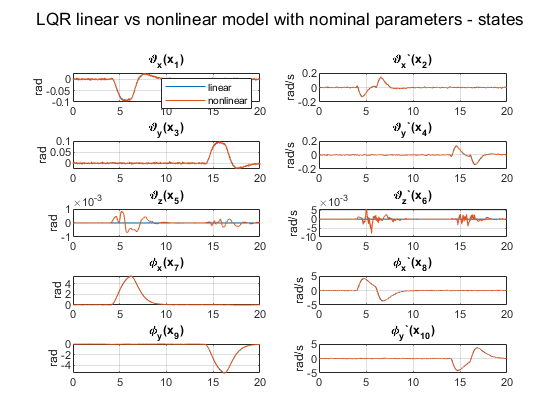

figure(201)
sgtitle('LQR linear vs nonlinear model with nominal parameters - states')

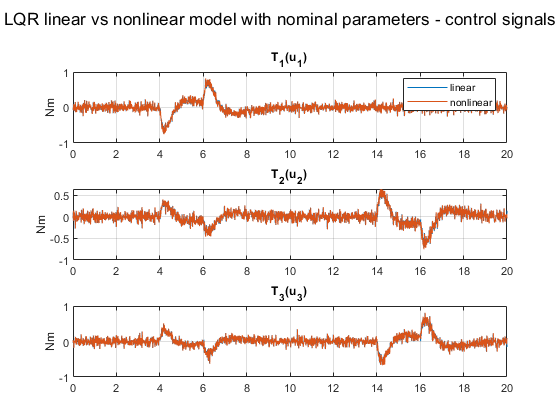

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 39.843095 seconds.


figure(202)
sgtitle('LQR linear vs nonlinear model with nominal parameters - control signals')
% complarison linear nonlinear disturbance rejection
nlsim(@nlin_model_wcu,-K_lqr,dist,t_d,P_wc,203,204);

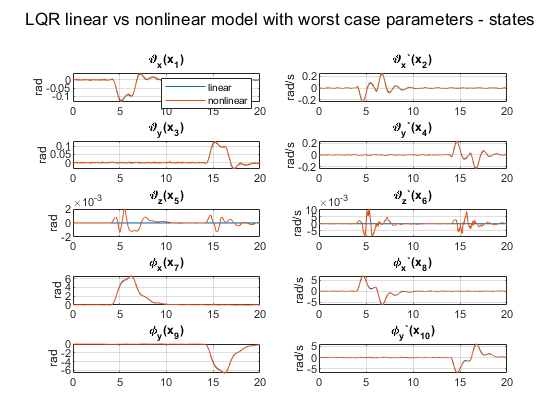

figure(203)
sgtitle('LQR linear vs nonlinear model with worst case parameters - states')

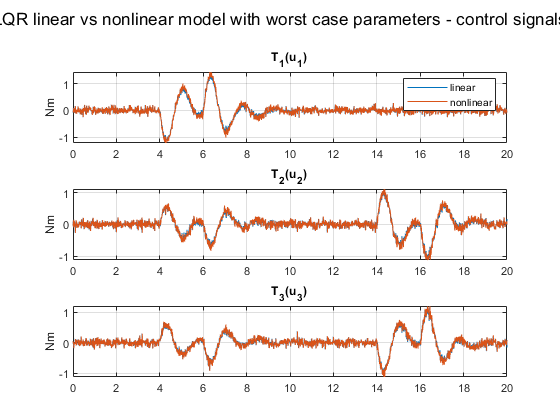

figure(204)
sgtitle('LQR linear vs nonlinear model with worst case parameters - control signals')

### Singular value plot for disturbance rejection fonominal and worst case model

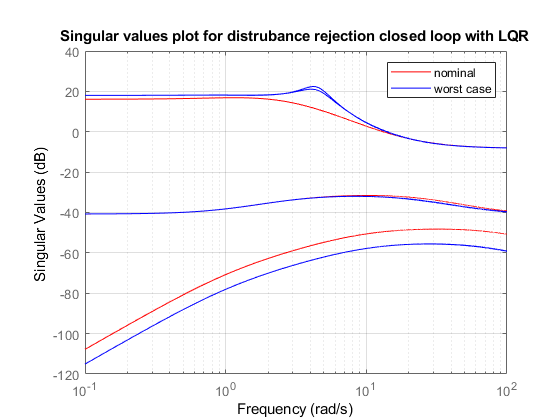

% plot singular values of distrurbance rejection loop
figure(301)
sigma(lft(P,-K_lqr),'r',lft(P_wc,-K_lqr),'b',(0.1:0.01:100));
legend('nominal','worst case');
grid on
title('Singular values plot for distrubance rejection closed loop with LQR')

## H-infinity controller design

Fixed structure - gain U=K*x;

%% H-infinity controller design fixed
% hinf fixed structure - gain
K_hinf 

K_hinf =   173.2508   77.4633   -0.2012    2.9678    1.3062  -20.7797    1.8181    3.4908    0.0043    0.0049
  -82.7147  -44.7815  152.2795   52.3834  -41.9845    6.0208   -0.6652   -2.1440    1.5273    2.7051
  -63.8915  -42.2659 -146.7962  -57.9439  -61.3589    6.8772   -0.3581   -2.0293   -1.6450   -2.9035


## **Comparison of H-infinity and LQR **

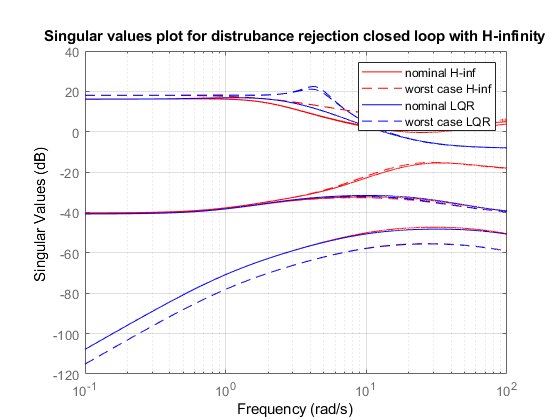

% plot singular values of distrurbance rejection loop
figure(302)
sigma(lft(P,-K_hinf),'r',lft(P_wc,-K_hinf),'--r',lft(P,-K_lqr),'b',lft(P_wc,-K_lqr),'--b',(0.1:0.01:100));
legend('nominal H-inf','worst case H-inf','nominal LQR','worst case LQR');
grid on
title('Singular values plot for distrubance rejection closed loop with H-infinity')

## Complarison H-infinity and LQR linear models

kill_figures([303,304,305,306]);

Figure 303 not opened
Figure 304 not opened
Figure 305 not opened
Figure 306 not opened


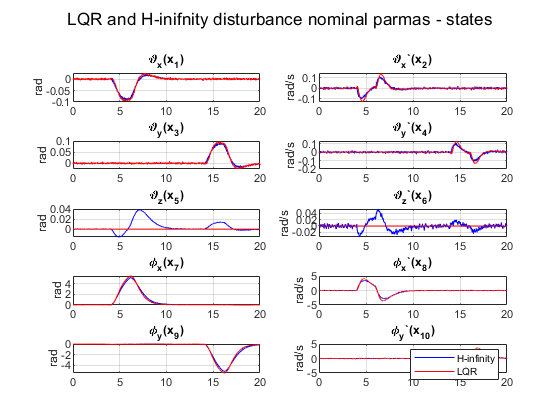

linsim(lft(P,-K_hinf),'b',dist,t_d,303,304);
linsim(lft(P,-K_lqr),'r',dist,t_d,303,304);
figure(303)
sgtitle('LQR and H-inifnity disturbance nominal parmas - states')
legend('H-infinity','LQR')

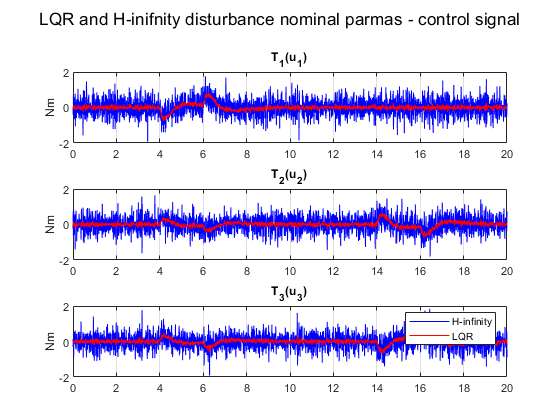

figure(304)
sgtitle('LQR and H-inifnity disturbance nominal parmas - control signal')
legend('H-infinity','LQR')

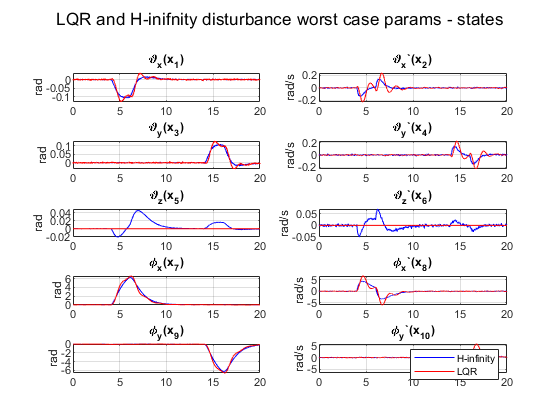

linsim(lft(P_wc,-K_hinf),'b',dist,t_d,305,306);
linsim(lft(P_wc,-K_lqr),'r',dist,t_d,305,306);
figure(305)
sgtitle('LQR and H-inifnity disturbance worst case params - states')
legend('H-infinity','LQR')

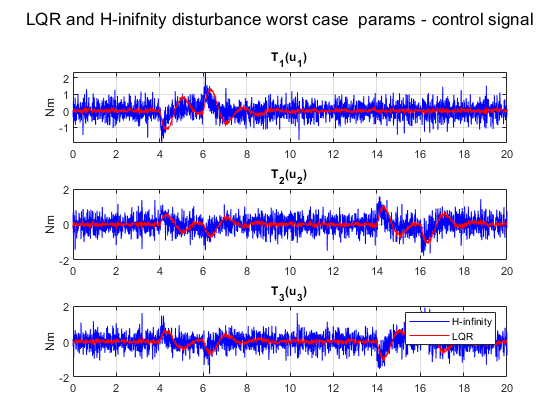

figure(306)
sgtitle('LQR and H-inifnity disturbance worst case  params - control signal')
legend('H-infinity','LQR')

### Bode diagram of comparison 

kill_figures([312,311]);

Figure 312 not opened
Figure 311 not opened


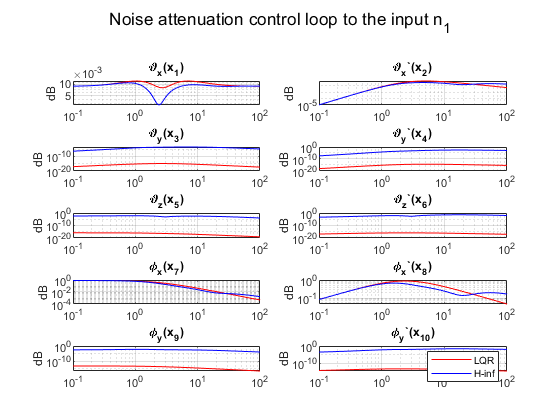

H_lqr = lft(P,-K_lqr);
H_hinf = lft(P,-K_hinf);
bodemg(H_lqr(1:10,1),'r',311);
hold on
bodemg(H_hinf(1:10,1),'b',311);
legend('LQR', 'H-inf')
sgtitle('Noise attenuation control loop to the input n_1');

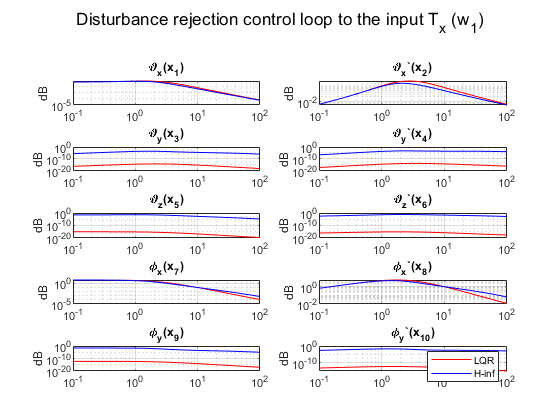


bodemg(H_lqr(1:10,5),'r',312);
hold on
bodemg(H_hinf(1:10,5),'b',312);
legend('LQR', 'H-inf')
sgtitle('Disturbance rejection control loop to the input T_x (w_1)');

## Complarison H-infinity and nonlinear model

kill_figures([307,308,309,310]);

Figure 307 not opened
Figure 308 not opened
Figure 309 not opened
Figure 310 not opened


nlsim(@nlin_model_n,-K_hinf,dist,t_d,P_wc,307,308);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 41.727729 seconds.


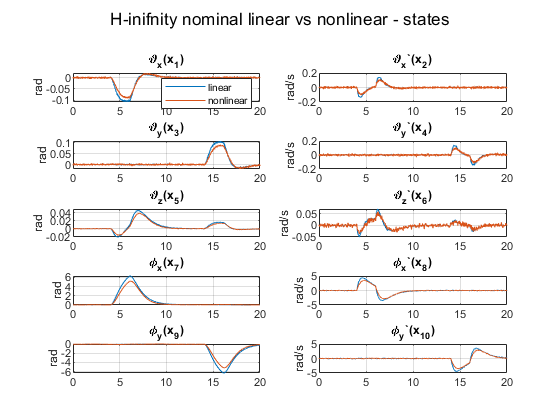

figure(307);
sgtitle('H-inifnity nominal linear vs nonlinear - states')

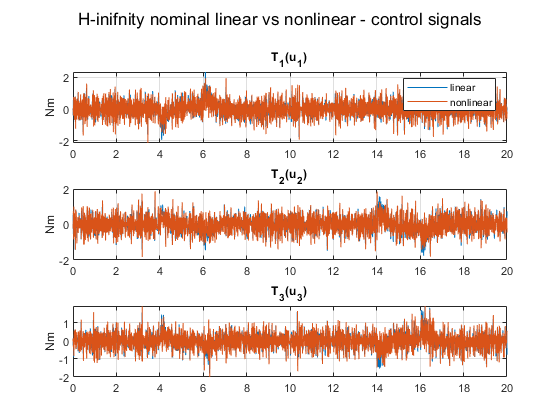

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 39.210774 seconds.


figure(308)
sgtitle('H-inifnity nominal linear vs nonlinear - control signals')
nlsim(@nlin_model_wcu,-K_hinf,dist,t_d,P,309,310);

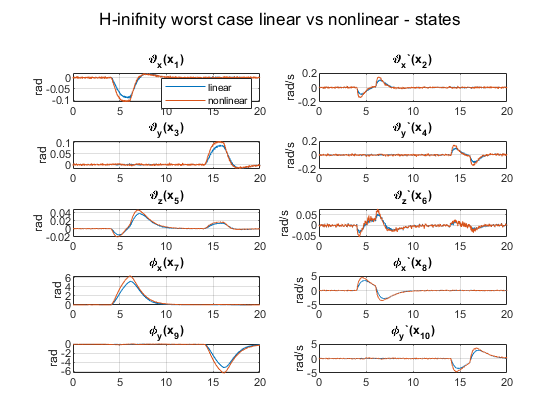

figure(309)
sgtitle('H-inifnity worst case linear vs nonlinear - states')

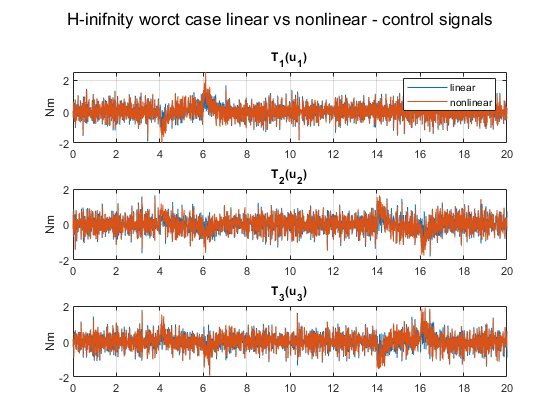

figure(310)
sgtitle('H-inifnity worct case linear vs nonlinear - control signals')

## State space H-infinity controller 

State space controller

%% H-infinity controller 
fprintf('H-inf state space controller has %d states \n',ns);

H-inf state space controller has 3 states 


K_hinf_ss


K_hinf_ss =
 
  A = 
           x1      x2      x3
   x1  -16.89  -29.72   2.562
   x2  -37.44   -72.8   25.68
   x3  -7.435  -22.91  -3.672
 
  B = 
            u1       u2       u3       u4       u5       u6       u7       u8       u9      u10
   x1   -92.35   -787.4   -339.9   -378.2   -623.6   -53.21   -30.82   -60.52   -13.98   -47.37
   x2   -171.5   -758.7    -1615    -1096   -782.2    49.37   -77.49   -84.53   -64.37   -114.4
   x3    100.2   -884.1   -206.5   -221.8     -358    -43.4   -3.258   -73.41  -0.6915   -29.64
 
  C = 
            x1       x2       x3
   y1    1.718    1.646   -4.928
   y2    -4.68   -6.224    3.724
   y3    3.777    5.297  -0.4349
 
  D = 
            u1       u2       u3       u4       u5       u6       u7       u8       u9      u10
   y1    25.63   -211.7   -3.365    -12.5   -25.51    3.831    6.991   -14.12    6.001  0.09425
   y2     8.87    84.86   -127.1   -109.6   -113.7    8.132      -11    2.846   -7.803   -10.85
   y3    33.86    81.67    

## Comparison LQR and H-inifnity state space

kill_figures([404,405,406,407]);

Figure 404 not opened
Figure 405 not opened
Figure 406 not opened
Figure 407 not opened


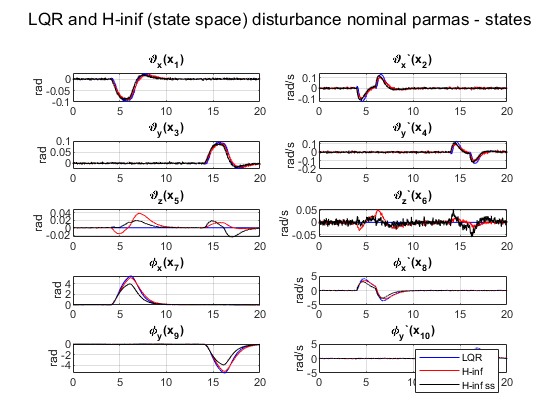

linsim(lft(P,-K_lqr),'b',dist,t_d,404,405);
linsim(lft(P,-K_hinf),'r',dist,t_d,404,405);
linsim(lft(P,K_hinf_ss),'k',dist,t_d,404,405);
figure(404)
sgtitle('LQR and H-inif (state space) disturbance nominal parmas - states')
legend('LQR','H-inf','H-inf ss')

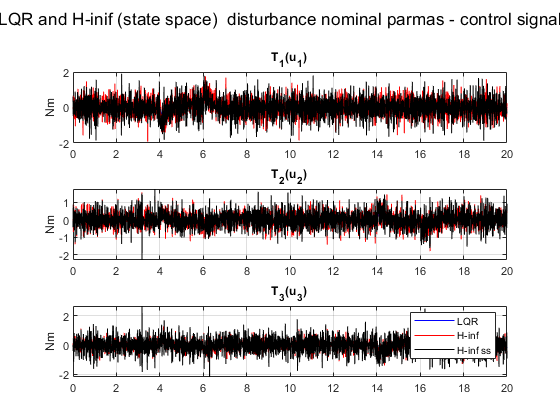

figure(405)
sgtitle('LQR and H-inif (state space)  disturbance nominal parmas - control signal')
legend('LQR','H-inf','H-inf ss')

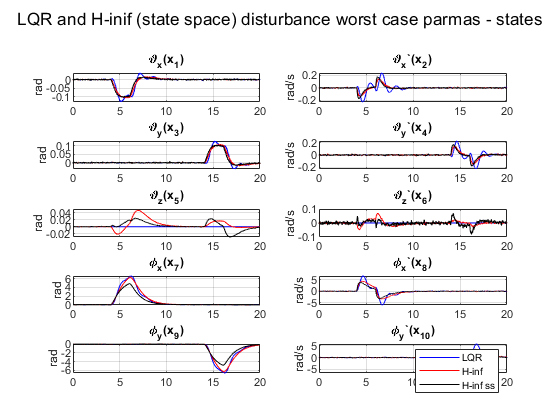

linsim(lft(P_wc,-K_lqr),'b',dist,t_d,406,407);
linsim(lft(P_wc,-K_hinf),'r',dist,t_d,406,407);
linsim(lft(P_wc,K_hinf_ss),'k',dist,t_d,406,407);
figure(406)
sgtitle('LQR and H-inif (state space) disturbance worst case parmas - states')
legend('LQR','H-inf','H-inf ss')

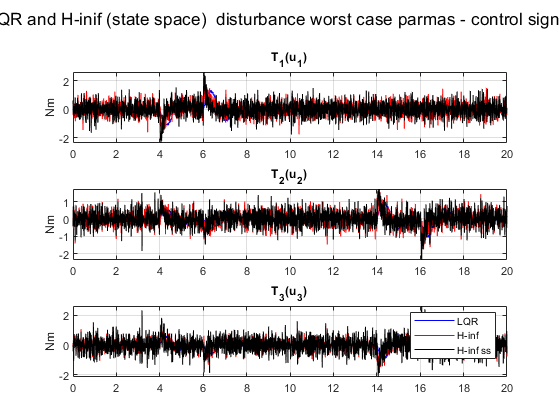

figure(407)
sgtitle('LQR and H-inif (state space)  disturbance worst case parmas - control signal')
legend('LQR','H-inf','H-inf ss')

## Complarison H-infinity and nonlinear model

kill_figures([507,508,509,510]);

Figure 507 not opened
Figure 508 not opened
Figure 509 not opened
Figure 510 not opened


nlsim(@nlin_model_n,K_hinf_ss,dist,t_d,P_wc,507,508);

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 39.181575 seconds.


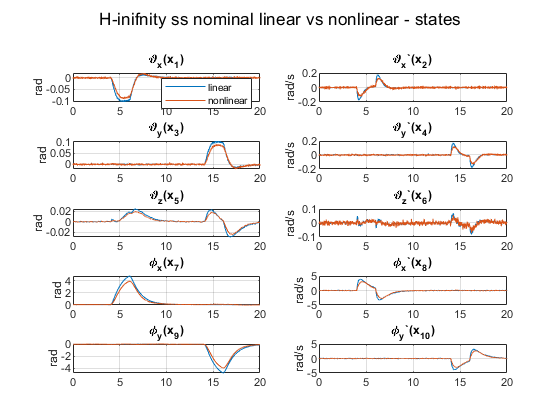

figure(507);
sgtitle('H-inifnity ss nominal linear vs nonlinear - states')
hold off;

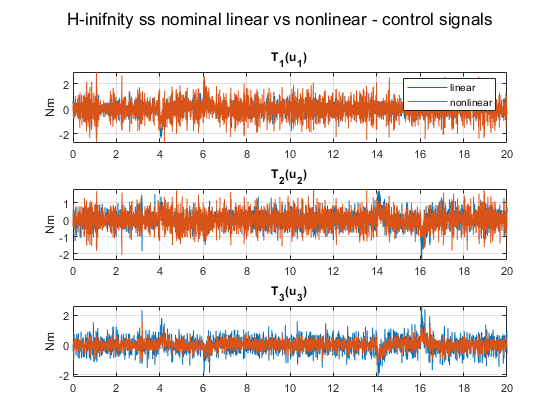

nonlinear system simulation
Nonlinear simulation: 20.00 sec / 20.00 sec
Elapsed time is 44.563419 seconds.


figure(508)
sgtitle('H-inifnity ss nominal linear vs nonlinear - control signals')
hold off;
nlsim(@nlin_model_wcu,K_hinf_ss,dist,t_d,P,509,510);

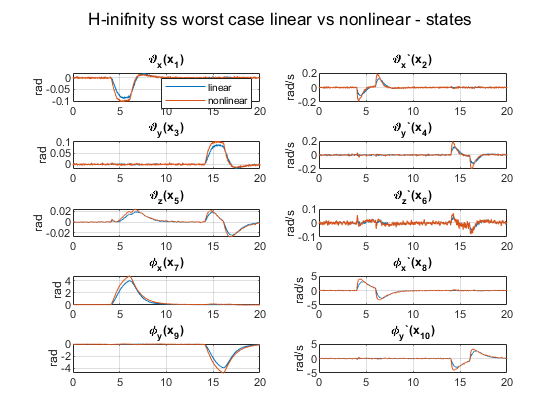


figure(509)
sgtitle('H-inifnity ss worst case linear vs nonlinear - states')

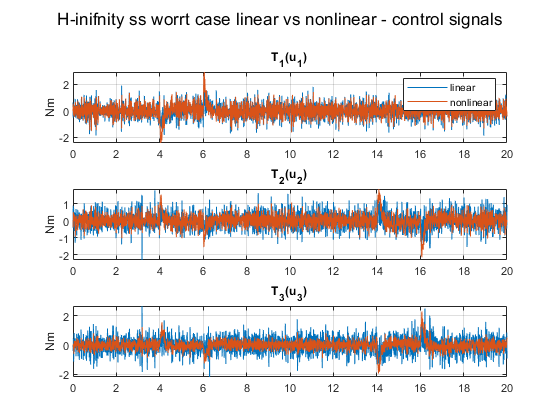

figure(510)
sgtitle('H-inifnity ss worrt case linear vs nonlinear - control signals')

## Bode diagram of LQR, H-infinity gain and H-infinity state space

We can see that state space H-infinity controller has lowest gain for almost all the transfrer functions on the plot making it the most robustly stable one.

kill_figures([506,512]);

Figure 506 not opened
Figure 512 not opened


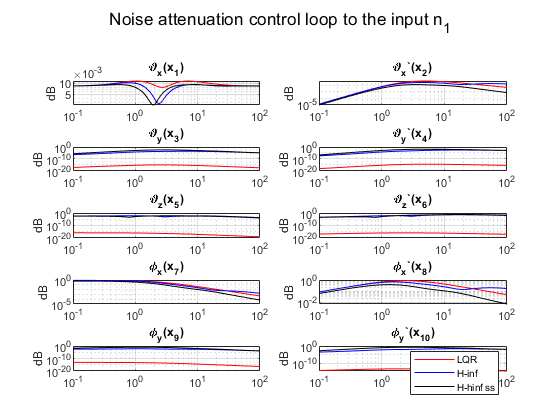

figure(506)
H_hinf_ss = lft(P,K_hinf_ss);
bodemg(H_lqr(1:10,1),'r',506);
hold on
bodemg(H_hinf(1:10,1),'b',506);
bodemg(H_hinf_ss(1:10,1),'k',506);
legend('LQR', 'H-inf', 'H-hinf ss')
sgtitle('Noise attenuation control loop to the input n_1');

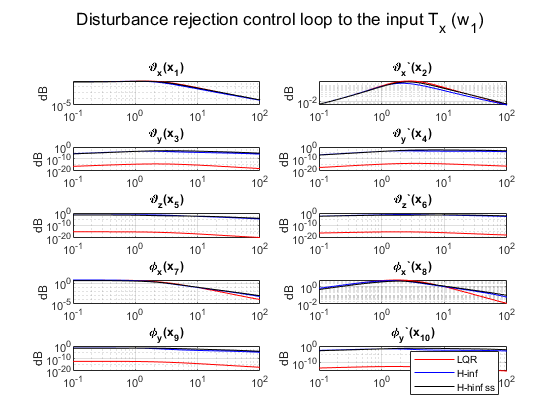

bodemg(H_lqr(1:10,5),'r',512);
hold on
bodemg(H_hinf(1:10,5),'b',512);
bodemg(H_hinf_ss(1:10,5),'k',512);
legend('LQR', 'H-inf','H-hinf ss')
sgtitle('Disturbance rejection control loop to the input T_x (w_1)');

## H-infintiy norms for nominal and worst case parameter linear model comparison of LQR, fixed H-inifnity and state space H-Infinity controller

hinfnorm(lft(P,-K_lqr))

ans = 6.9632

hinfnorm(lft(P,-K_hinf))

ans = 6.5297

hinfnorm(lft(P,K_hinf_ss))

ans = 4.9773

hinfnorm(lft(P_wc,-K_lqr))

ans = 13.1776

hinfnorm(lft(P_wc,-K_hinf))

ans = 8.0404

hinfnorm(lft(P_wc,K_hinf_ss))

ans = 5.8505

## Stability margins for nominal and worst case parameter linear model comparison of LQR, fixed H-inifnity and state space H-Infinity controller

diskmargin(G_n,K_lqr)

ans = struct with fields:
     GainMargin: [0.8536 1.1715]
    PhaseMargin: [-9.0299 9.0299]
     DiskMargin: 0.1579
     LowerBound: 0.1579
     UpperBound: 0.1582
      Frequency: 3.5389


diskmargin(G_n,K_hinf)

ans = struct with fields:
     GainMargin: [0.8081 1.2375]
    PhaseMargin: [-12.1195 12.1195]
     DiskMargin: 0.2123
     LowerBound: 0.2123
     UpperBound: 0.2127
      Frequency: 2.9208


diskmargin(G_n,-K_hinf_ss)

ans = struct with fields:
     GainMargin: [0.8422 1.1874]
    PhaseMargin: [-9.7930 9.7930]
     DiskMargin: 0.1713
     LowerBound: 0.1713
     UpperBound: 0.1717
      Frequency: 3.4945


diskmargin(wcu.G,K_lqr)

ans = struct with fields:
     GainMargin: [0.9471 1.0559]
    PhaseMargin: [-3.1145 3.1145]
     DiskMargin: 0.0544
     LowerBound: 0.0544
     UpperBound: 0.0545
      Frequency: 4.3736


diskmargin(wcu.G,K_hinf)

ans = struct with fields:
     GainMargin: [0.8720 1.1468]
    PhaseMargin: [-7.8215 7.8215]
     DiskMargin: 0.1367
     LowerBound: 0.1367
     UpperBound: 0.1370
      Frequency: 10.3358


diskmargin(wcu.G,-K_hinf_ss)

ans = struct with fields:
     GainMargin: [0.9086 1.1006]
    PhaseMargin: [-5.4822 5.4822]
     DiskMargin: 0.0958
     LowerBound: 0.0958
     UpperBound: 0.0959
      Frequency: 25.6104


## Closed loop singular value plot comparison

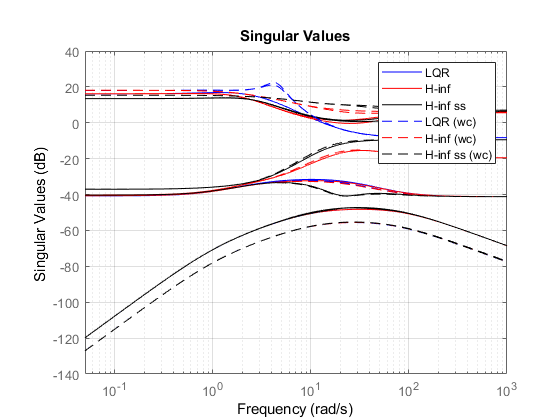

% plot singular values of distrurbance rejection loop
figure(520)
sigma(lft(P,-K_lqr),'b',lft(P,-K_hinf),'r',lft(P,K_hinf_ss),'k',lft(P_wc,-K_lqr),'--b',lft(P_wc,-K_hinf),'--r',lft(P_wc,K_hinf_ss),'--k',(0.05:0.01:1000));
legend('LQR','H-inf','H-inf ss','LQR (wc)','H-inf (wc)','H-inf ss (wc)');
grid on;